# Probabilistic Principle Component Analysis For Time Delay Interferometry

Quentin Baghi has introduced a method to construct the TDI combinations with Principle Component Analysis (PCA). The travelling time of the light between two distant spacedracfts is not required in this method.

Now, we propose an method to form the TDI combinations with PCA from the perspective of probability, and it helps us to deal with the missing data case. We call this method as PPCA-TDI.

## Data Simulation

Like Baghi, we use the simulated data to validate the PPCATDI. The following equations show the noise requirements of LISA.

- Laser frequency noise: $S_{p}(f)=\left(\frac{28.2 \mathrm{~Hz} \cdot \mathrm{Hz}^{-1 / 2}}{\nu_{0}}\right)^{2},$

- Stochastic noise: $S_{n}(f)=\frac{S_{a}(f)}{(2 \pi f c)^{2}}+\left(\frac{2 \pi f}{c}\right)^{2} S_{\mathrm{oms}}(f),$

where $\nu_0 =\frac{c}{1064\times {10}^{-9} \;\mathrm{m}}$ is the central frequency of the lasers, $S_a \left(f\right)$ is the test-mass acceleration noise PSD (in ${\mathrm{m}}^2 {\mathrm{s}}^{-4} {\mathrm{Hz}}^{-1}$) and $S_{\mathrm{oms}} \left(f\right)$ is the PSD representing all other path length noises in the measurement (in ${\mathrm{m}}^2 {\mathrm{Hz}}^{-1}$).

- Test-mass acceleration noise: $S_a \left(f\right)=a_{\mathrm{TM}}^2 \left\lbrack 1+{\left(\frac{f_1 }{f}\right)}^2 \right\rbrack \left\lbrack 1+{\left(\frac{f}{f_2 }\right)}^4 \right\rbrack ,$

- Optical metrology system (OMS) noise: $S_{\mathrm{oms}} \left(f\right)=a_{\mathrm{oms}}^2 \left\lbrack 1+{\left(\frac{f_3 }{f}\right)}^4 \right\rbrack \ldotp$

where $a_{\mathrm{TM}} =3\times {10}^{-15} {\;\mathrm{ms}}^{-2} ,a_{\mathrm{oms}} =15\times {10}^{-12} {\;\mathrm{mHz}}^{-\frac{1}{2}} ,f_1 =4\times {10}^{-4} \;\mathrm{Hz},f_2 =8\times {10}^{-3} \;\mathrm{Hz},f_3 =2\times {10}^{-3} \;\mathrm{mHz}\ldotp$

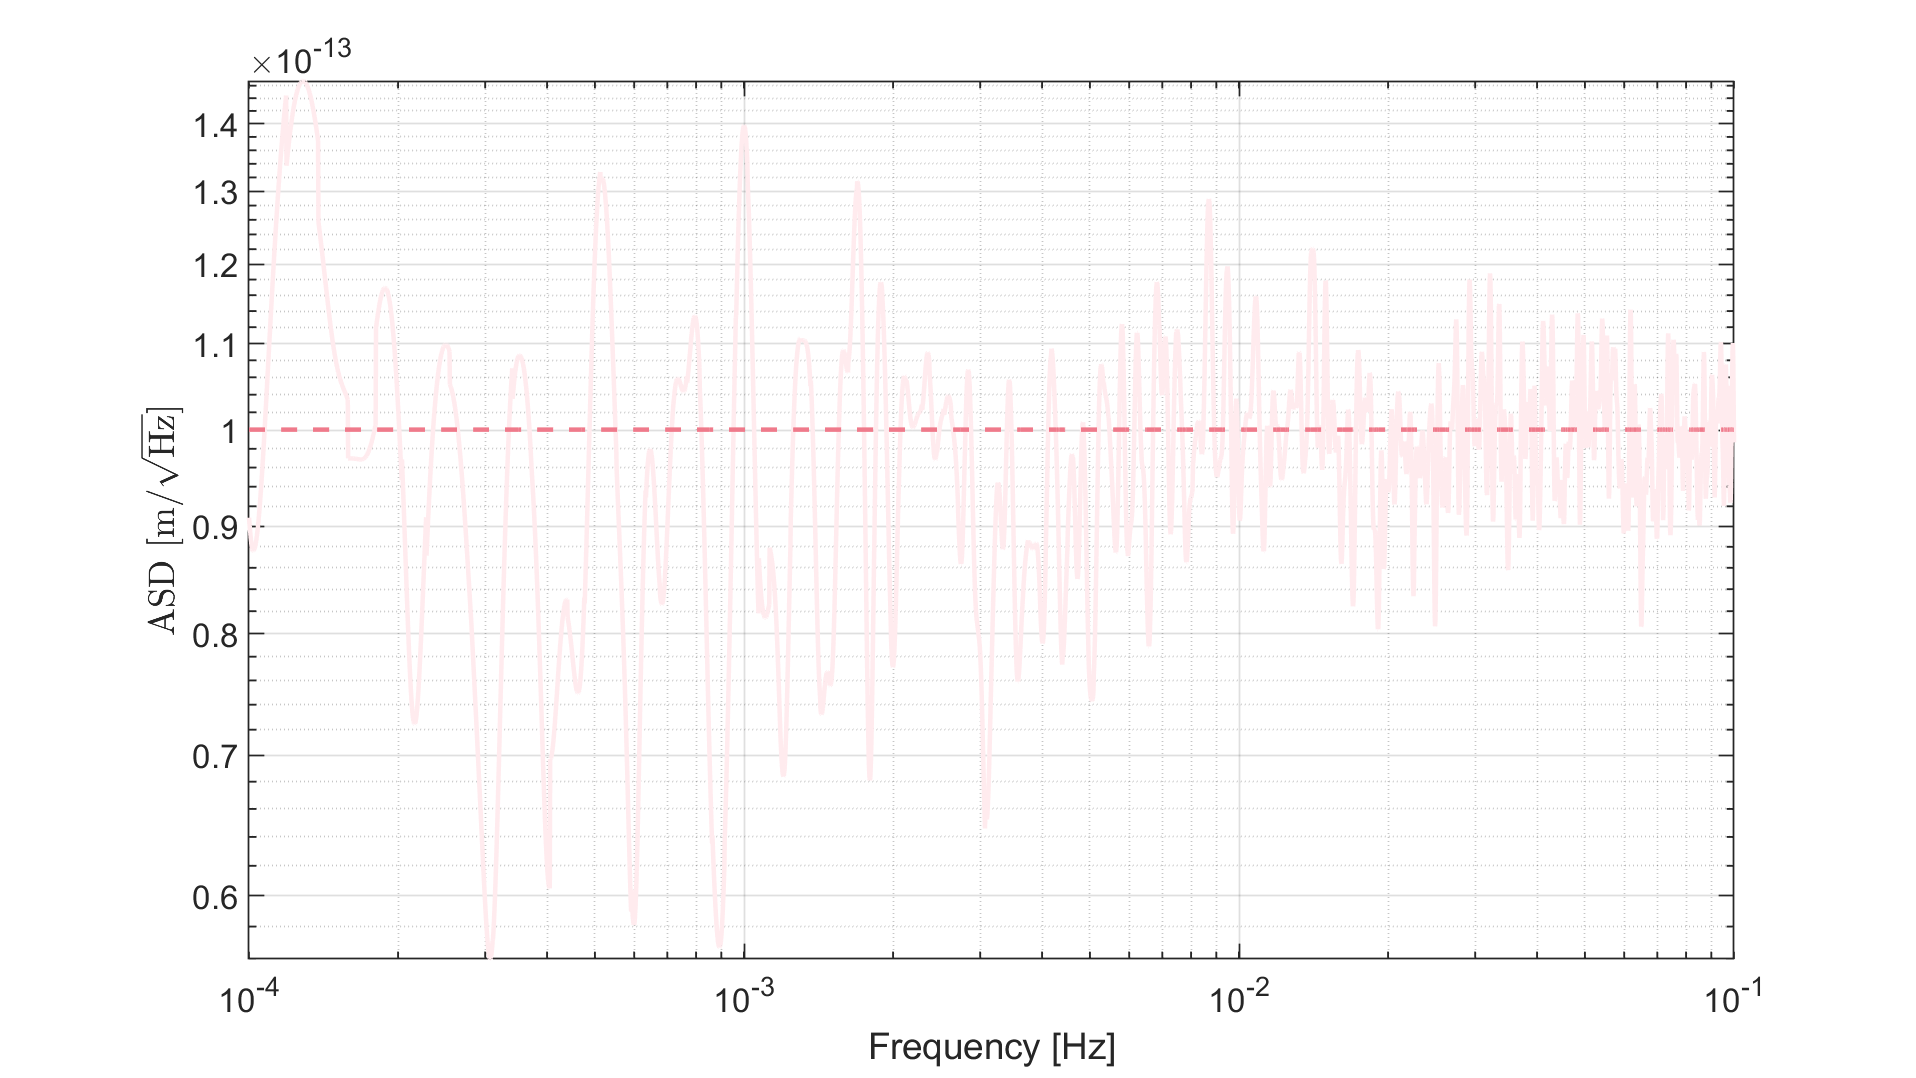

clc;
clear;
close all;
warning off;

% -------- %
% constant %
% -------- %
% simulation parameter
% sampling rate
fs = 2;                                 % in Hz
% duration of simulation
dura = 86400;                          % in seconds
% length
len = fs * dura;
% speed of light
c = 299792458;                          % in m/s
% PSDs parameter
nu_0 = c / (1064e-9);                   % in Hz
a_TM = 3e-15;                           % in m/s
a_oms = 15e-12;                         % in m/s^{1/2}
f_0 = 2e-3;                             % in Hz
f_1 = 4e-4;                             % in Hz
f_2 = 8e-3;                             % in Hz
f_3 = 2e-6;                             % in Hz

% -------------- %
% PSDs of noises %
% -------------- %
% test-mass acceleration noise
S_a = @(f) sqrt(a_TM^2 * (1 + (f_1 ./ f).^2) .* (1 + (f / f_2).^4));
% OMS noise
S_oms = @(f) sqrt(a_oms^2 * (1 + (f_3 ./ f).^4));
% stochastic noise
S_n = @(f) sqrt(a_TM^2 .* (1 + (f_1 ./ f).^2) .* (1 + (f / f_2).^4) ./ (2 .* pi .* f .* c).^2 + (2 .* pi .* f ./ c).^2 .* a_oms^2 .* (1 + (f_3 ./ f).^4));
% laser frequecny noise
S_p = @(f) sqrt((28.2 / nu_0)^2 * f ./ f);

% time series of noises
% white noise
white = randn(len, 1);
f = 1e-4: 1e-5: 1e-1;
% laser frequency noise
laser_freq_noise = time_series_from_asd(S_p, white, fs);
% stochastic noise
stochastic_noise = time_series_from_asd(S_n, white, fs);

new_figure;
[X_laser, f_laser, C_laser] = lpsd(laser_freq_noise, @hann, 1e-4, 1e-1, 40000, 10000, 3, fs, 0.1);
loglog(f_laser, sqrt(X_laser .* C_laser.PSD), 'linewidth', 2.7, "LineStyle", "-", "Color", "#FFEBEE"); hold on;
loglog(f, S_p(f), 'linewidth', 2.7, "LineStyle", "--", "Color", "#EF7A8B");
grid on;
hold on;
xlabel('Frequency [Hz]', 'fontsize', 15);
ylabel('ASD [m/$\sqrt{\rm Hz}$]', 'fontsize', 15, "Interpreter", "latex");

set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);
